Textfile = load("W4.txt")

Textfile =           20         168         520        8436          75         -34         -49
          20         160         472        8440          34          -2         -53
          20         260         420        8536          34          -2         -53
          20         260         420        8536          51          20         -54
          20         224         496        8512          82          68         -34
          20         192         468        8488          48          63         -44
          20         232         476        8456          33          95         -68
          20         200         480        8432          58         131         -59
          20         236         452        8540          68         139         -62
          20         140         484        8488          71         164         -73


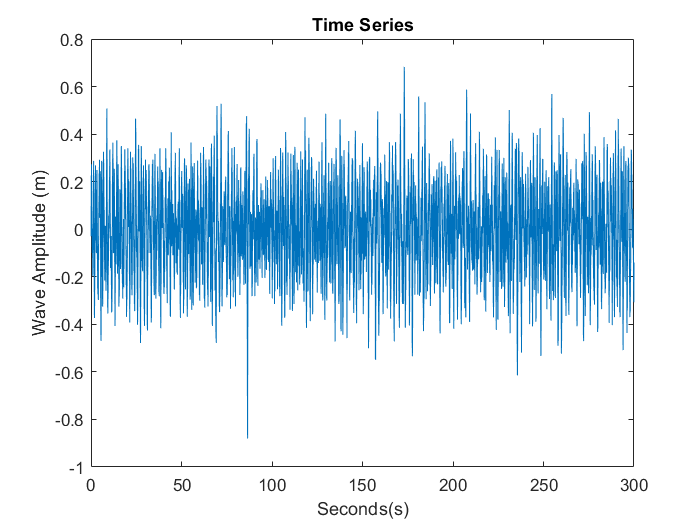

writematrix(Textfile, "W4.csv");
timeSeriesData = readtable("W4.csv");


N =  30000 - 1; 
timeSeriesData = detrend((timeSeriesData{:, 4}/8192*9.81)-9.81); %data is symmetric, *2 to account for contribution of other half 
fs = 100;
time = 1/fs*(0:(N));

plot(time(1:30000), timeSeriesData(1:30000)); %only plotting the real side of the dataset 
title("Time Series");
xlabel("Seconds(s)");
ylabel("Wave Amplitude (m)");